# Controller HIL Testing for Three-Phase PMSM with Two-Level Inverter

## Description 

This reference example showcases model-in-the-loop (MIL) and hardware-in-the-loop (HIL) testing of field-oriented control (FOC) running on a F28379D LaunchPad™ development kit for C2000™ Delfino™ MCU by Texas Instruments. The motor drive consists of a three-phase permanent magnet synchronous motor (PMSM) with a two-level inverter.

### **Learn how to:**

- Model and simulate a high-fidelity PMSM drive system digital twin, including ripples and switching harmonics

- Set up a HIL test system for testing FOC running on target hardware

- Perform interactive motor controller testing with Simulink® and MATLAB®

- Expedite motor controller development with automated and continuous HIL testing 

## **Supported Model-Based Design Use Cases **

This example supports the following simulation modes (see image below):

- Desktop MIL: Both the PMSM drive plant and motor controller run on the development computer. The PMSM drive is modeled using an average inverter, which uses PWM duty-cycle and DC voltage inputs and outputs the phase voltages. This plant model is hereafter referred to as average model. Use this simulation mode to test and verify the FOC controls against the electric drive in closed-loop desktop simulation.

- Real-time MIL: Both the PMSM drive plant and motor controller run in real-time on a Speedgoat HIL test system. Two variants are available for the simulation of the PMSM drive:

                    1. Average model: The PMSM with average inverter executes on the test system's multicore CPU.

                    2. Detailed model: The PMSM with switching inverter executes on a [Simulink-Programmable FPGA I/O](https://www.speedgoat.com/products-services/i-o-connectivity/simulink-programmable-fpga-i-o). The switching inverter is controlled by firing pulses produced by a PWM generator. This plant version provides the required resolution and fidelity for simulating high frequency switching dynamics such as current ripples and spatial harmonics.   

              Use this mode to validate real-time aspects of both plant and controller. The development computer is used to control the real-time simulation, fine-tune the PMSM drive and FOC parameters, and measure real-time signals including ripples and switching harmonics directly out of Simulink.

- HIL: Interface the FOC controller running on the intended target hardware with the PMSM drive detailed model running on the Speedgoat HIL test system. Use this mode to perform interactive and automated HIL testing of your embedded controller.

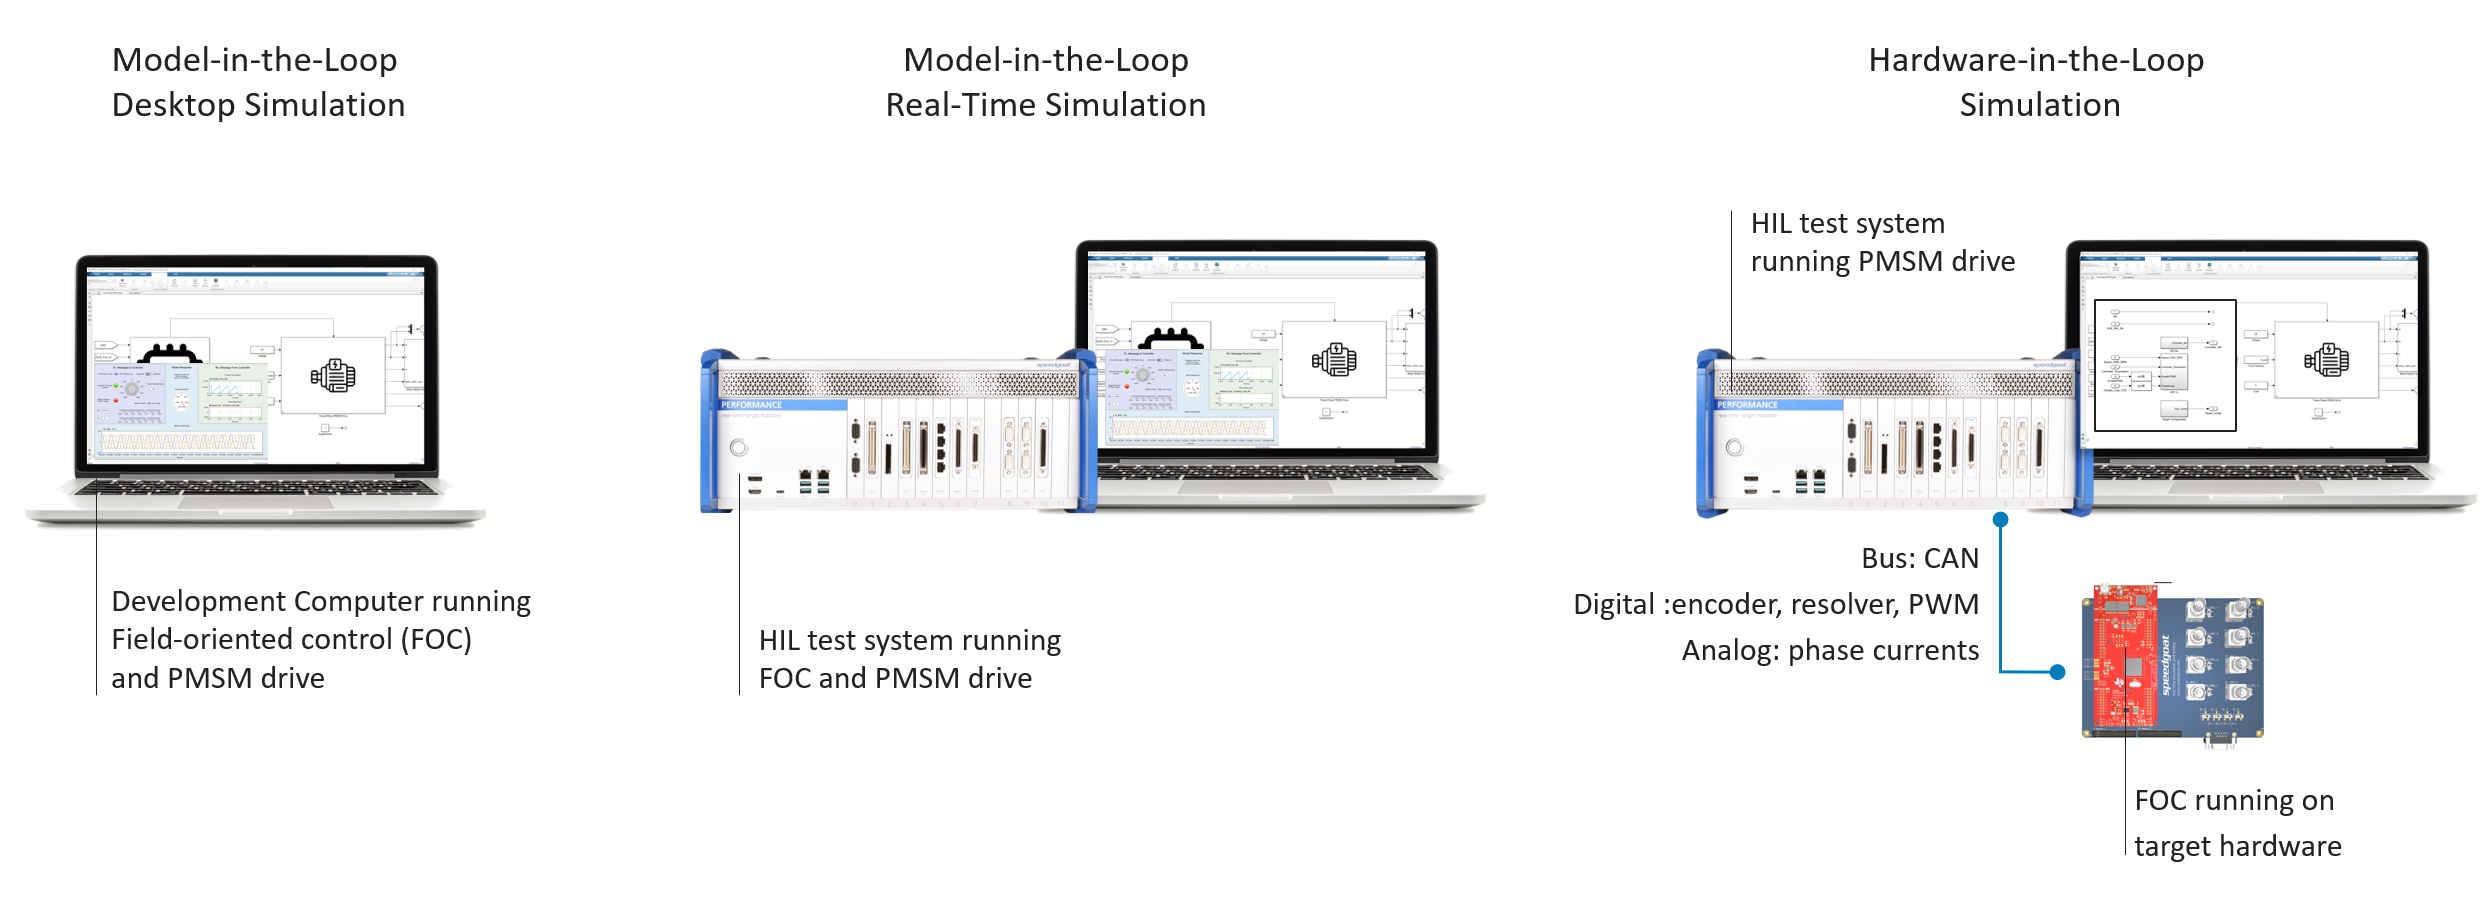

## System Requirements

The system requirements can differ based on the chosen simulation mode. Below, you will find the requirements for conducting controller HIL testing.

###     MathWorks® Products

- Simulink® Real-Time™

- Motor Control Blockset™

- Embedded Coder®

- C2000™ Microcontroller Blockset

- Simulink® Test™

###     Speedgoat Products

- [Performance Real-Time Target Machine](https://www.speedgoat.com/products-services/real-time-target-machines/performance-real-time-target-machine)

- [IO334: Programmable FPGA I/O module with Xilinx Kintex 7 + Analog I/O for Simulink ](https://www.speedgoat.com/products/simulink-programmable-fpgas-fpga-i-o-modules-io334)

- [IO3XX-21: Digital TTL pulse/encoder/SPI/I2C I/O support for Simulink](https://www.speedgoat.com/products/simulink-programmable-fpgas-fpga-i-o-modules-io3xx-21)

- [HDL Coder Integration Package](https://www.speedgoat.com/help/hdlcoder/page/index)

- [Motion Control HDL I/O Blockset](https://www.speedgoat.com/help/hdlcoder/page/sg_help_motioncontrol/index)

- [I/O Module supporting CAN (Controller Area Network)](https://www.speedgoat.com/products-services/communications-protocols/can)

- [Launchpad Development Kit](https://www.speedgoat.com/products/launchpad-development-kit)

## Exercises

### A. Fine Tune Controller Parameters Using Desktop Simulation 

You can control the simulation parameters programmatically and record the results of a simulation.

mdl = 'PMSM3P2LInverterCHILsystem';
open_system(mdl);
open(Simulink.BlockPath('PMSM3P2LInverterCHILsystem/User Interface'));

% Configure testbench for desktop MIL simulation using average model
set_param([bdroot '/Three-Phase PMSM System/SimulationVariant'], 'Value','1');

%Use a set of parameters for tuning
set_param([bdroot '/Three-Phase PMSM System/Speed_Cmd_rpm'], 'Value','600');
set_param([bdroot '/Three-Phase PMSM System/Closed_Loop_FOC'], 'Value','1');
set_param([bdroot '/Three-Phase PMSM System/EnablePWM'], 'Value','1');
set_param([bdroot '/Three-Phase PMSM System/Controller Parameters/Default Values'], 'Value','0');

%Choose Proportional and Integral Gains
set_param([bdroot '/Three-Phase PMSM System/Controller Parameters/Kp_S'], 'Value','0.1');
set_param([bdroot '/Three-Phase PMSM System/Controller Parameters/Ki_S'], 'Value','0.1');


% Start dekstop simulation
set_param(mdl,'SimulationCommand','Start','StopTime','5');
simOut = sim('PMSM3P2LInverterCHILsystem.slx','SimulationMode','normal');

% Get the most recently created Simulation Data Inspector run
experimentRunMIL = Simulink.sdi.Run.getLatest;
experimentRunMIL.Name = ['ControllerTuningMIL - ' char(experimentRunMIL.DateCreated)];
rotVelMIL = getSignalsByName(experimentRunMIL,'Motor Speed RPM');

set_param(mdl,'SimulationCommand','Start','StopTime','inf');

While the simulation runs, you can also use the user interface to tune of the speed controller PI gains and speed command to assess controller performance.

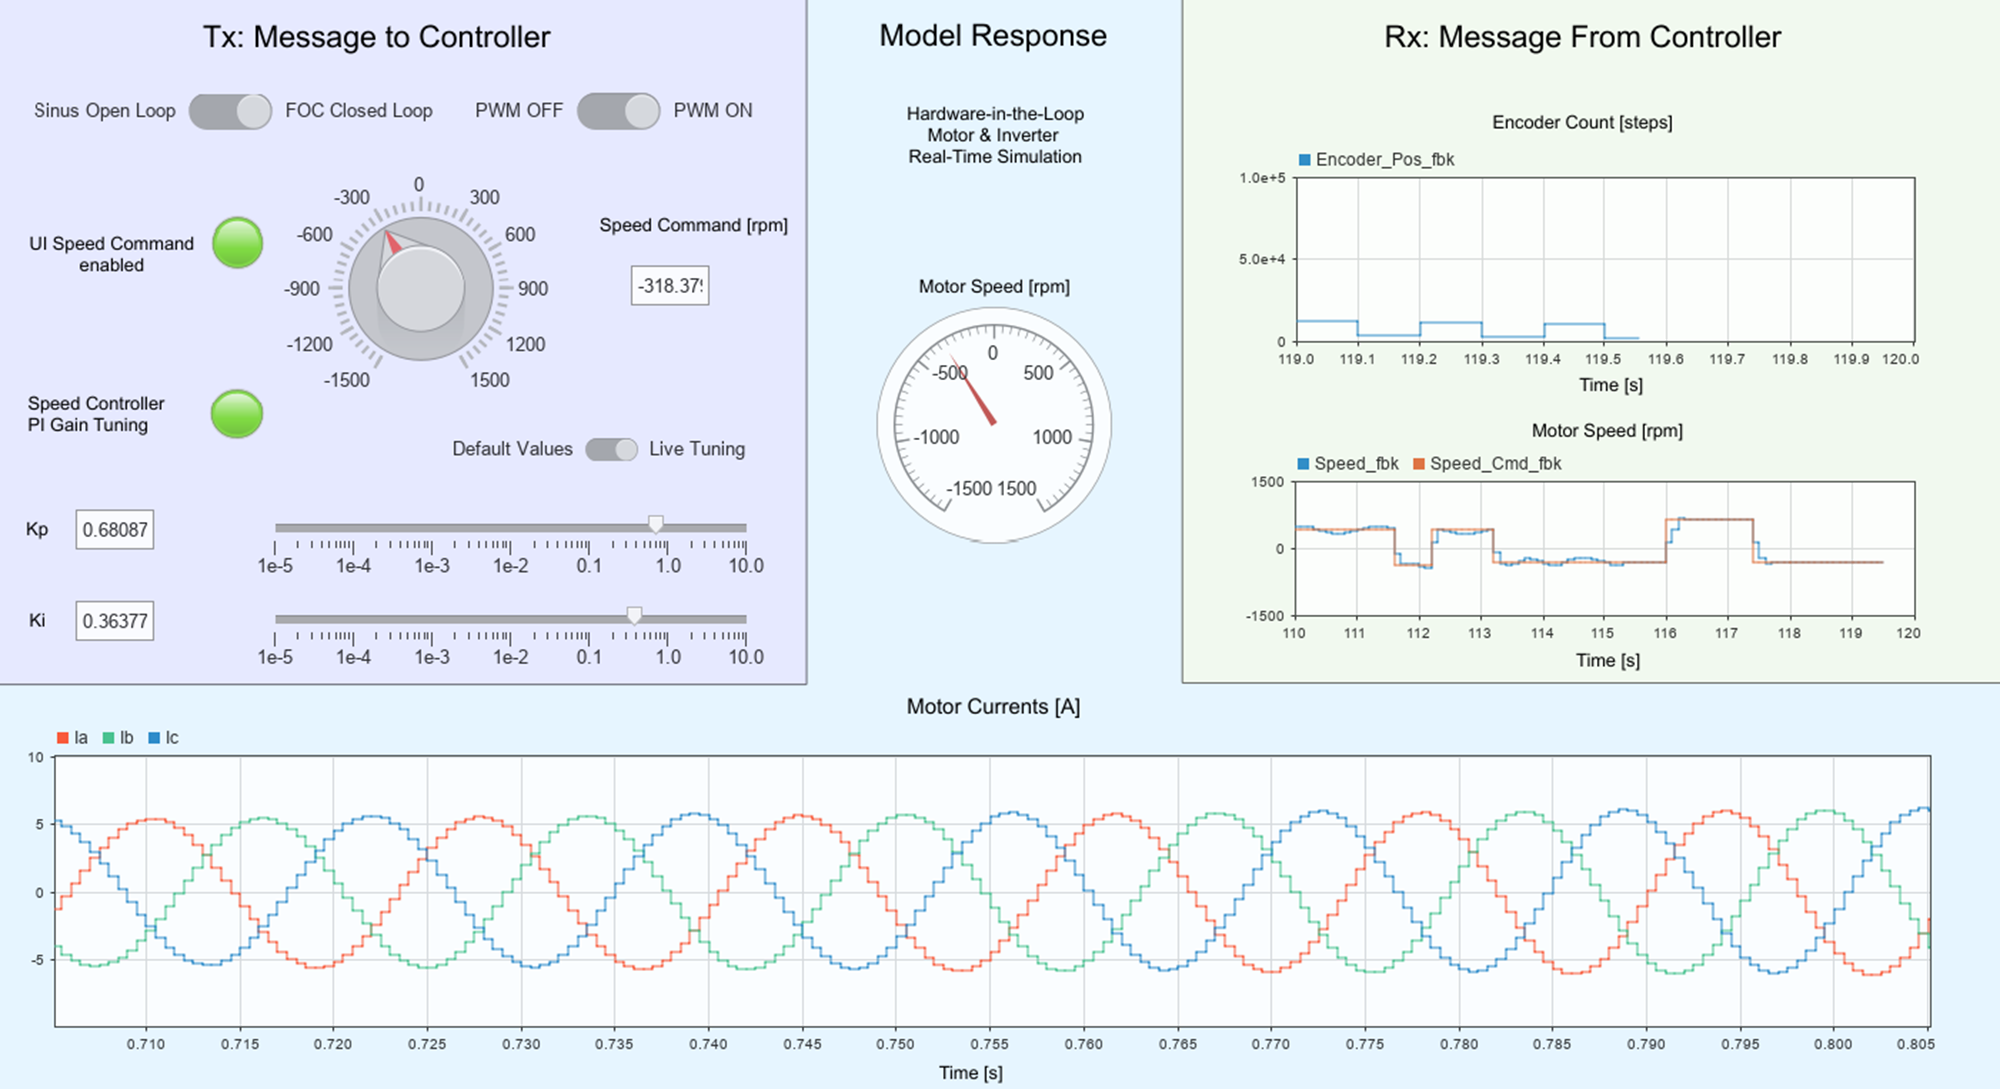

### B. Build and Validate the Detailed PMSM Drive Model

#### B1. Generate a Ready-to-Run FPGA Application from the Motor Drive Template

The present reference example contains a fixed bitstream that will program the IO334 FPGA to simulate a three-phase PMSM and a full switching two-level inverter for HIL testing. It is a good way to start experimenting with HIL setups and can serve as an example of architecture for your projects. To deploy your own models, you can use the [Three-Phase PMSM with Two-Level Inverter](https://www.speedgoat.com/help/hdlcoder/page/sg_help_motioncontrol/refentry_template_pmsm_inverter_c_hil) template from the [Speedgoat - Motion Control HDL I/O Blockset](https://www.speedgoat.com/help/hdlcoder/page/sg_help_motioncontrol/index): the template includes a similar plant as the one used in this example, but where many plant characteristics are parameterized and can be modified at model each startup or even tunable during runtime. To generate this configurable bitstream, simply follow the steps described in the [template](https://www.speedgoat.com/help/hdlcoder/page/sg_help_motioncontrol/refentry_template_pmsm_inverter_c_hil).

Once you have generated the bitstream using the script or the HDL workflow advisor, simply replace the block in the **PMSM_3P2LInverter_Plant_TBR** subsystem with the block in the generated model (*gm_PMSM3P2LInverterCHIL_slrt.slx*).

mdl = 'PMSM3P2LInverterCHILsystem';
open_system(mdl);
open(Simulink.BlockPath('PMSM3P2LInverterCHILsystem/Three-Phase PMSM System/Three-Phase PMSM Drive/PMSM and inverter with switching dynamics/PMSM_3P2L_Inverter_Plant_TBR'));

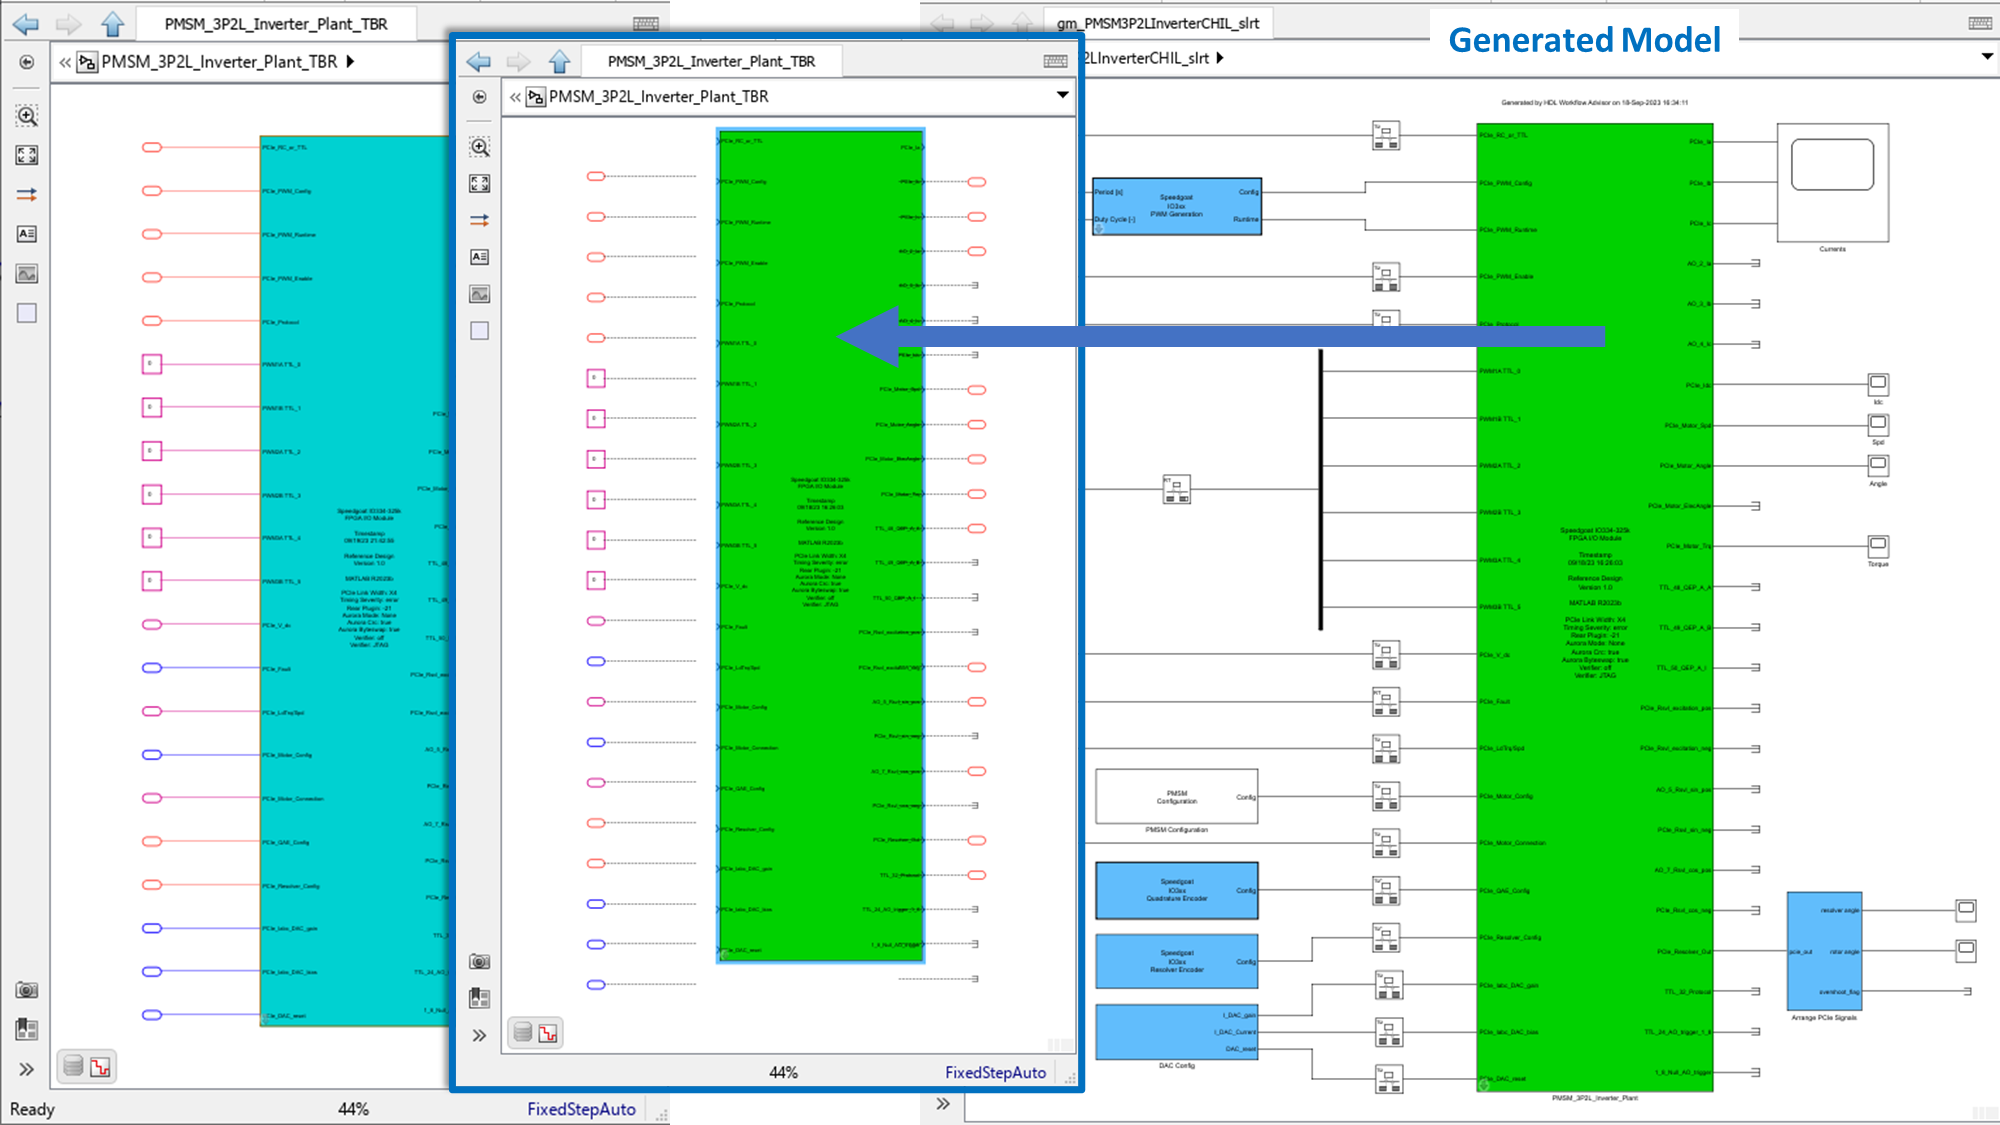

You also need to add your bitstream (*.mcs file generated from running HDL Workflow Advisor on the template) to the project. For example, you can place it in the *SupportFiles/Bitstreams* folder and add the file to the Simulink project.

#### B2. Validate the Detailed PMSM Drive Model 

To check the proper deployement of the full switching inverter, you can compare it with the average inverter model, either using the user interface or the following commands:

mdl = 'PMSM3P2LInverterCHILsystem';
open_system(mdl);
open(Simulink.BlockPath('PMSM3P2LInverterCHILsystem/User Interface'));

% Configure testbench for Real-time Model in the loop with switching inverter
set_param([bdroot '/Three-Phase PMSM System/SimulationVariant'], 'Value','2')


%Use the same set of parameters for tuning
set_param([bdroot '/Three-Phase PMSM System/Speed_Cmd_rpm'], 'Value','600')
set_param([bdroot '/Three-Phase PMSM System/Closed_Loop_FOC'], 'Value','1')
set_param([bdroot '/Three-Phase PMSM System/EnablePWM'], 'Value','1')
set_param([bdroot '/Three-Phase PMSM System/Controller Parameters/Default Values'], 'Value','0')

%Choose the same Proportional and Integral Gains
set_param([bdroot '/Three-Phase PMSM System/Controller Parameters/Kp_S'], 'Value','0.1')
set_param([bdroot '/Three-Phase PMSM System/Controller Parameters/Ki_S'], 'Value','0.1')

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Build the Simulink model
slbuild(mdl);   
  
% Download and install the real-time application on the target machine
tg.load(mdl);
  
% Start simulation of real-time application
tg.setStopTime(5);

tg.start;
pause(10);
% Get the most recently created Simulation Data Inspector run
experimentRunHIL = Simulink.sdi.Run.getLatest;
experimentRunHIL.Name = ['ControllerTuningHIL - ' char(experimentRunHIL.DateCreated)];
rotVelHIL = getSignalsByName(experimentRunHIL,'Motor Speed RPM');

% Plot the rotor velocity from the average inverter against the full
% switching inverter.
Simulink.sdi.setSubPlotLayout(2,1);
plotOnSubPlot(rotVelMIL,1,1,true);
plotOnSubPlot(rotVelHIL,2,1,true);
Simulink.sdi.view;

set_param(mdl,'SimulationCommand','Start','StopTime','inf');

#### Observe PMSM Drive Switching Dynamics 

You can use real-time MIL simulation to observe current ripples. To do so, you must connect at least one of the current outputs to an oscilloscope : you can use the [IO334 I/O Box](https://www.speedgoat.com/products-services/accessories/panels-and-boxes/io334-i-o-box) and connect the channel 2,3 and 4.

Ripples in an open-loop control system are readily observable, especially when using a low PWM (Pulse-Width Modulation) frequency. For instance, you can employ the following parameters for demonstration:

- Controller Mode: Sinusoidal open-loop control

- PWM Frequency: 1000 Hz

- Motor Speed: 300 RPM

mdl = 'PMSM3P2LInverterCHILsystem';
open_system(mdl);
open(Simulink.BlockPath('PMSM3P2LInverterCHILsystem/User Interface'));


% Configure testbench for Real-time Model in the loop with switching inverter
set_param([bdroot '/Three-Phase PMSM System/SimulationVariant'], 'Value','2')

% Configure the controller with the parameters for ripple observation
set_param([bdroot '/Three-Phase PMSM System/Speed_Cmd_rpm'], 'Value','300')
set_param([bdroot '/Three-Phase PMSM System/Closed_Loop_FOC'], 'Value','0')
set_param([bdroot '/Three-Phase PMSM System/EnablePWM'], 'Value','1')

dd = Simulink.data.dictionary.open('PMSM3P2LInverterDd.sldd');
setValue(getEntry(dd.getSection('Design Data'), 'PWM_frequency'), 1000);

dd.saveChanges;

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Build the Simulink model
slbuild(mdl);   
  
% Download and install the real-time application on the target machine
tg.load(mdl);
  
% Start simulation of real-time application
tg.setStopTime(60);

tg.start;
pause(10);

%Revert PWM frequency value in the data dictionnary 
dd = Simulink.data.dictionary.open('PMSM3P2LInverterDd.sldd');
setValue(getEntry(dd.getSection('Design Data'), 'PWM_frequency'), 20000);

dd.saveChanges;


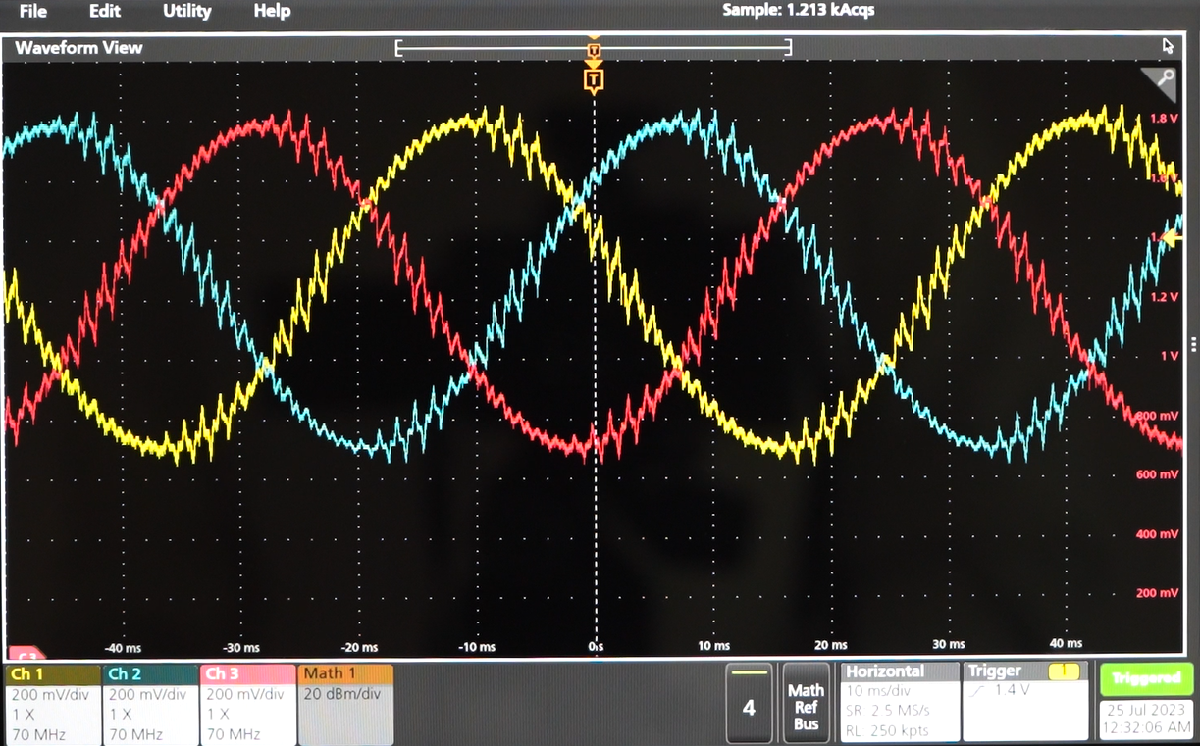

### C. Configure the Testbench for HIL Simulation

#### C1. Generate Code and Deploy Controller Logic to Target Hardware

This section instructs how to generate code and run the FOC algorithm on the F28379D LaunchPad™ development kit for C2000™ Delfino™ MCU by Texas Instruments. For that you first need to connect to connect it to your development computer using the mini-USB cable.

% Open model containing controller logic for F28379D target hardware
mdl = 'F28379DFirmware';
open_system(mdl);

% Connect target hardware to host computer (USB)

% Build and Deploy Code to target hardware
slbuild(mdl);

#### C2. Connect Target Hardware to HIL Test System

This reference example is specifically designed to run with the [Launchpad Development Kit](https://www.speedgoat.com/products/launchpad-development-kit) which greatly simplifies the interface between the test system's I/O modules and the controller. To set it up, simply connect the 98-Pin Analog cable from the IO334, the 68 pin Digital cable from the IO3xx-21 I/O interface extension and the D-sub 9 cable from the port 1 of the IO611 (the bottom port). Finally, ensure the jumper configuration matches the picture below, and connect the F28379D LaunchPad™ to a power supply using the Mini-USB cable (e.g. from the development computer or the USB-A port of the target machine).

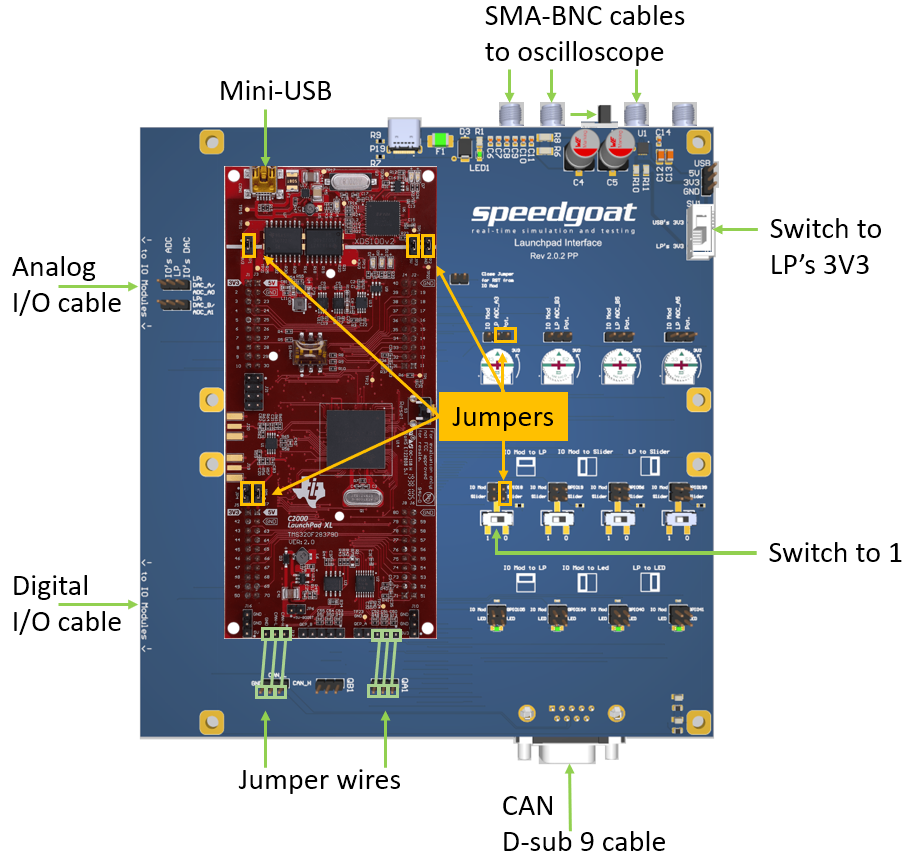

Alternatively, you can use a terminal board and the I/O box to manually wire the I/O modules to the controller.

The following tables provides a detailed pin mapping between the F28379D LaunchPad™,  Speedgoat IO334 Simulink-Programmable FPGA I/O Module and Speedgoat CAN I/O Module.

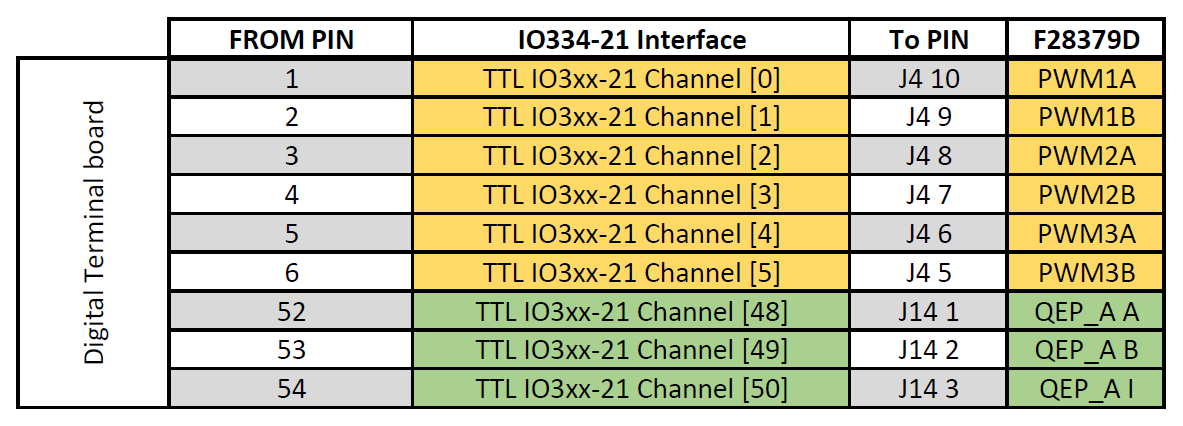

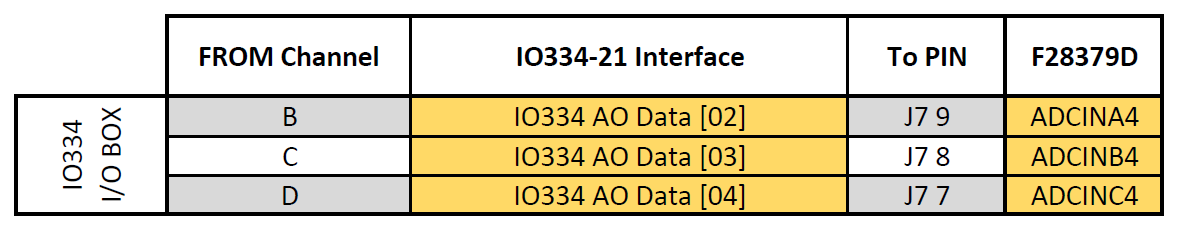

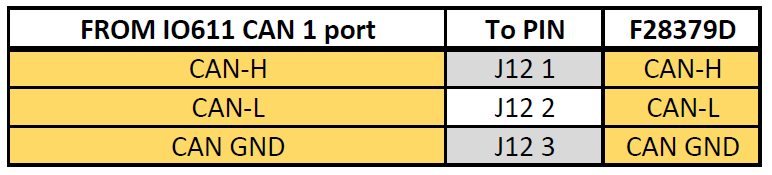

#### C3. Calibrate the ADCs

You can use the following commands to calibrate  the ADCs of the controller.

tg = slrealtime;
mdl = 'ADCCalibrationCAN';
open_system(mdl, 'loadonly');

% Build and Download
            
rtwbuild(mdl);
% Run and Plot Logged Data
load(tg, mdl);
tg.start;
pause(5);
tg.stop;

runObj = Simulink.sdi.Run.getLatest;
Ia_Signal = runObj.getSignalsByName('Ia_fbk');
Ib_Signal = runObj.getSignalsByName('Ib_fbk');
Ia_data = Ia_Signal.Values.Data;
Ib_data = Ib_Signal.Values.Data;

%Removing bad data
Ia_data=Ia_data(1000:end);
Ib_data=Ib_data(1000:end);

Ia_data(Ia_data==0) = [];
Ib_data(Ib_data==0) = [];

avgI_aOffset = sum(Ia_data) / length(Ia_data);
avgI_bOffset = sum(Ib_data) / length(Ib_data);

if abs(avgI_aOffset)<=20 && abs(avgI_bOffset)<=20
    dd = Simulink.data.dictionary.open('PMSM3P2LInverterDd.sldd');
    setValue(getEntry(dd.getSection('Design Data'), 'Ia_offset'),avgI_aOffset);
    setValue(getEntry(dd.getSection('Design Data'), 'Ib_offset'),avgI_bOffset);
    dd.saveChanges;
else 
    fprintf(' WARNING Calibration did not work : unrealistic offset \n')
end

%Close model
close_system(mdl, 0);

Offsets are saved in the main model's data dictionary. You can port them to the controller by re-running section C1. Alternatively, they will be sent to the controller through CAN during simulation.

### D. Controller Hardware-in-the-Loop Testing

#### D1. Perform Interactive Testing using Simulink Dashboard

This section provides instructions on using Simulink to conduct interactive HIL testing for assessing the impact of inverter faults.

mdl = 'PMSM3P2LInverterCHILsystem';
tg = slrealtime;
open_system(mdl);

% Configure testbench for HIL simulation using switching inverter and CAN
% interface (use 2 for Real-time model in the loop with switching inverter)
set_param([bdroot '/Three-Phase PMSM System/SimulationVariant'], 'Value','3') 

% Build the Simulink model
rtwbuild(mdl);  
  
% % Download and install the real-time application on the target machine
load(tg, mdl);
  
% Start simulation of real-time application
tg.start;
set_param([bdroot '/Three-Phase PMSM System/Speed_Cmd_rpm'], 'Value','500')
set_param([bdroot '/Three-Phase PMSM System/Closed_Loop_FOC'], 'Value','1')
pause(5)
set_param([bdroot '/Three-Phase PMSM System/Fault Trigering/Short_A'], 'Value','1') 
pause(5)
set_param([bdroot '/Three-Phase PMSM System/Closed_Loop_FOC'], 'Value','0')
pause(20)
tg.stop
%Switch back to default configuration
set_param([bdroot '/Three-Phase PMSM System/Closed_Loop_FOC'], 'Value','1')
set_param([bdroot '/Three-Phase PMSM System/Fault Trigering/Short_A'], 'Value','0')

Launch the Simulink user interface and activate the 'Faults UI' option. This allows you to toggle various faults on and off, enabling you to assess the controller's response. The image below, shows the results of a short circuit fault.

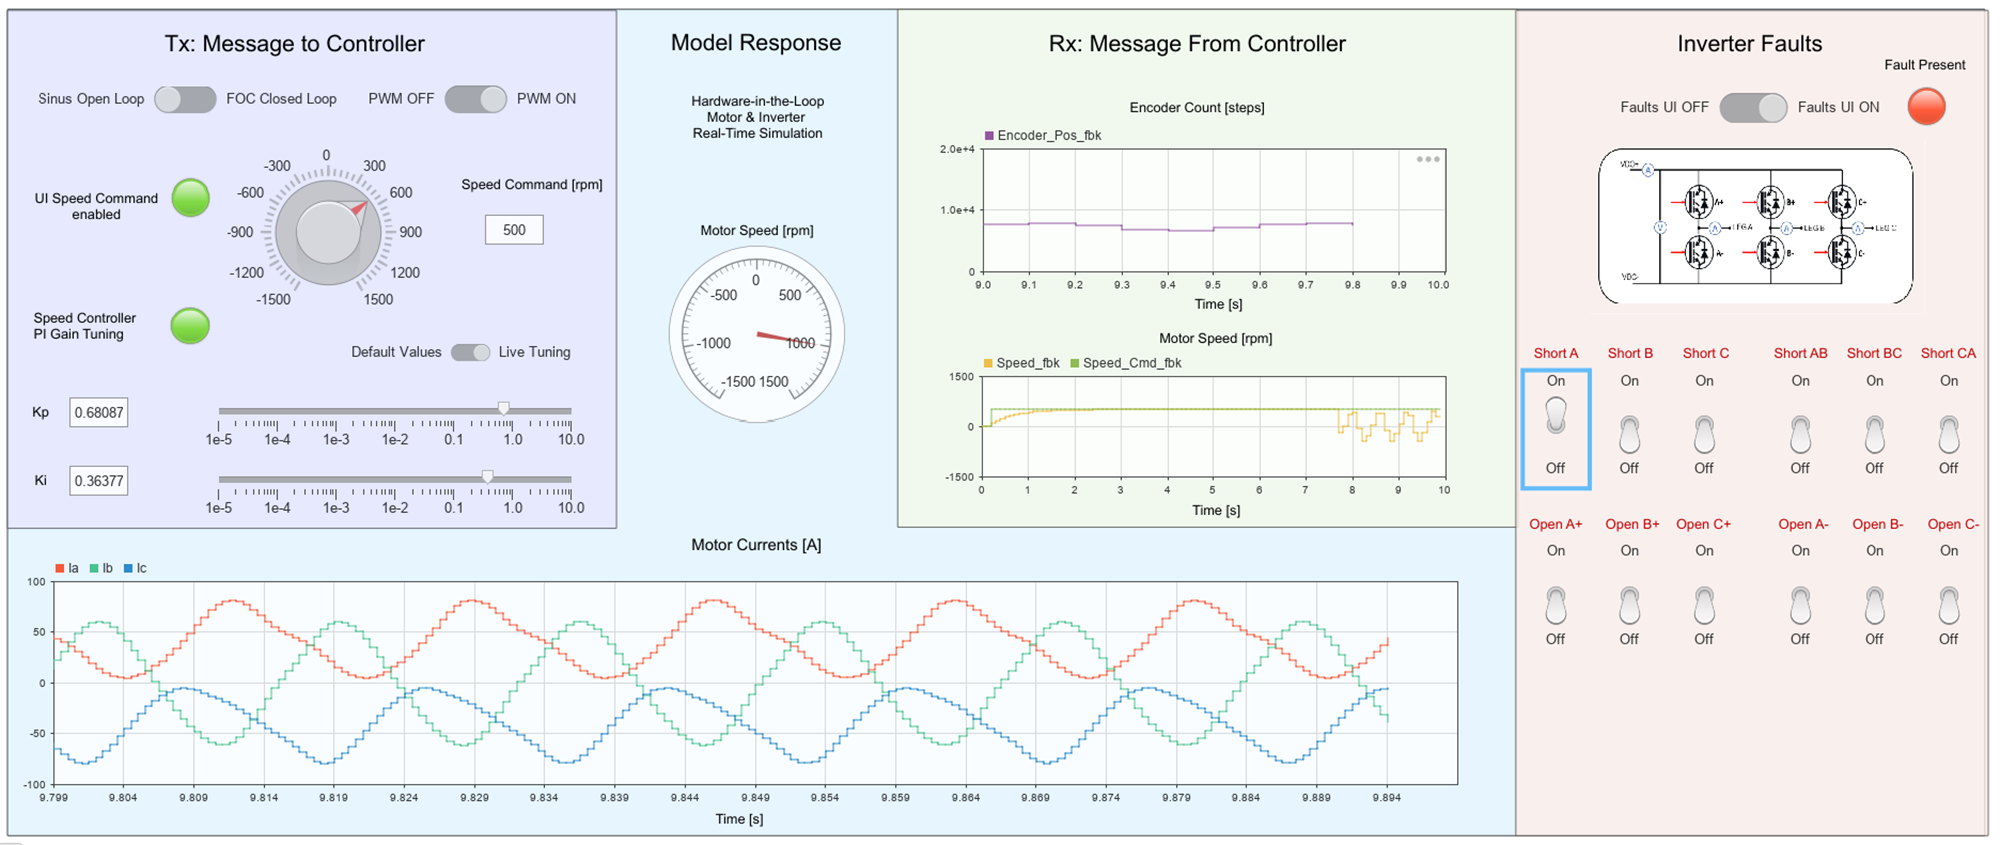 

#### D2. Automate Testing 

This section shows how to further automated HIL testing of the FOC embedded controller using Simulink Test.

Different test examples have been setup in a test suite using a command lines to create send the commands to the controller as well as control the conditions of the test (voltage, faults, etc.). You can also use the Test Manager to inspect the results.

open('Controller_HIL_CAN_Harness')

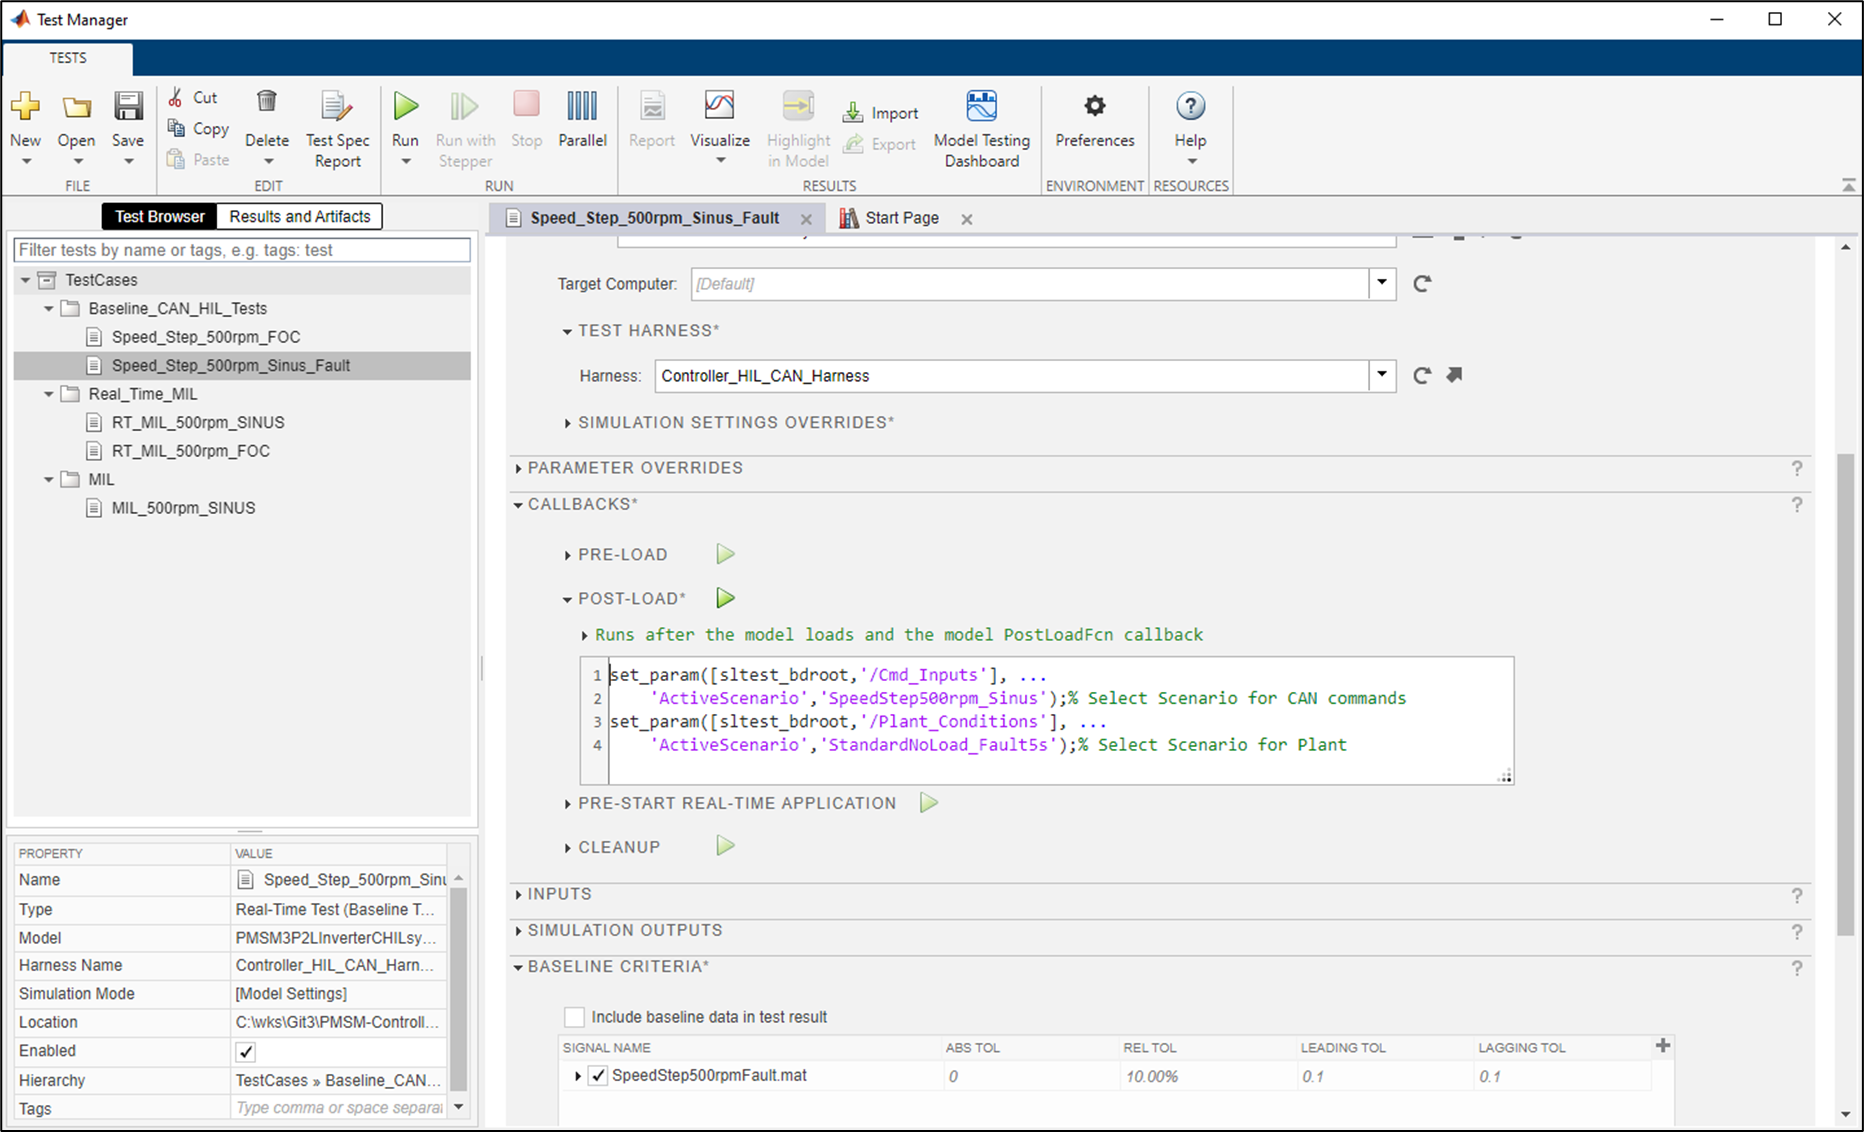

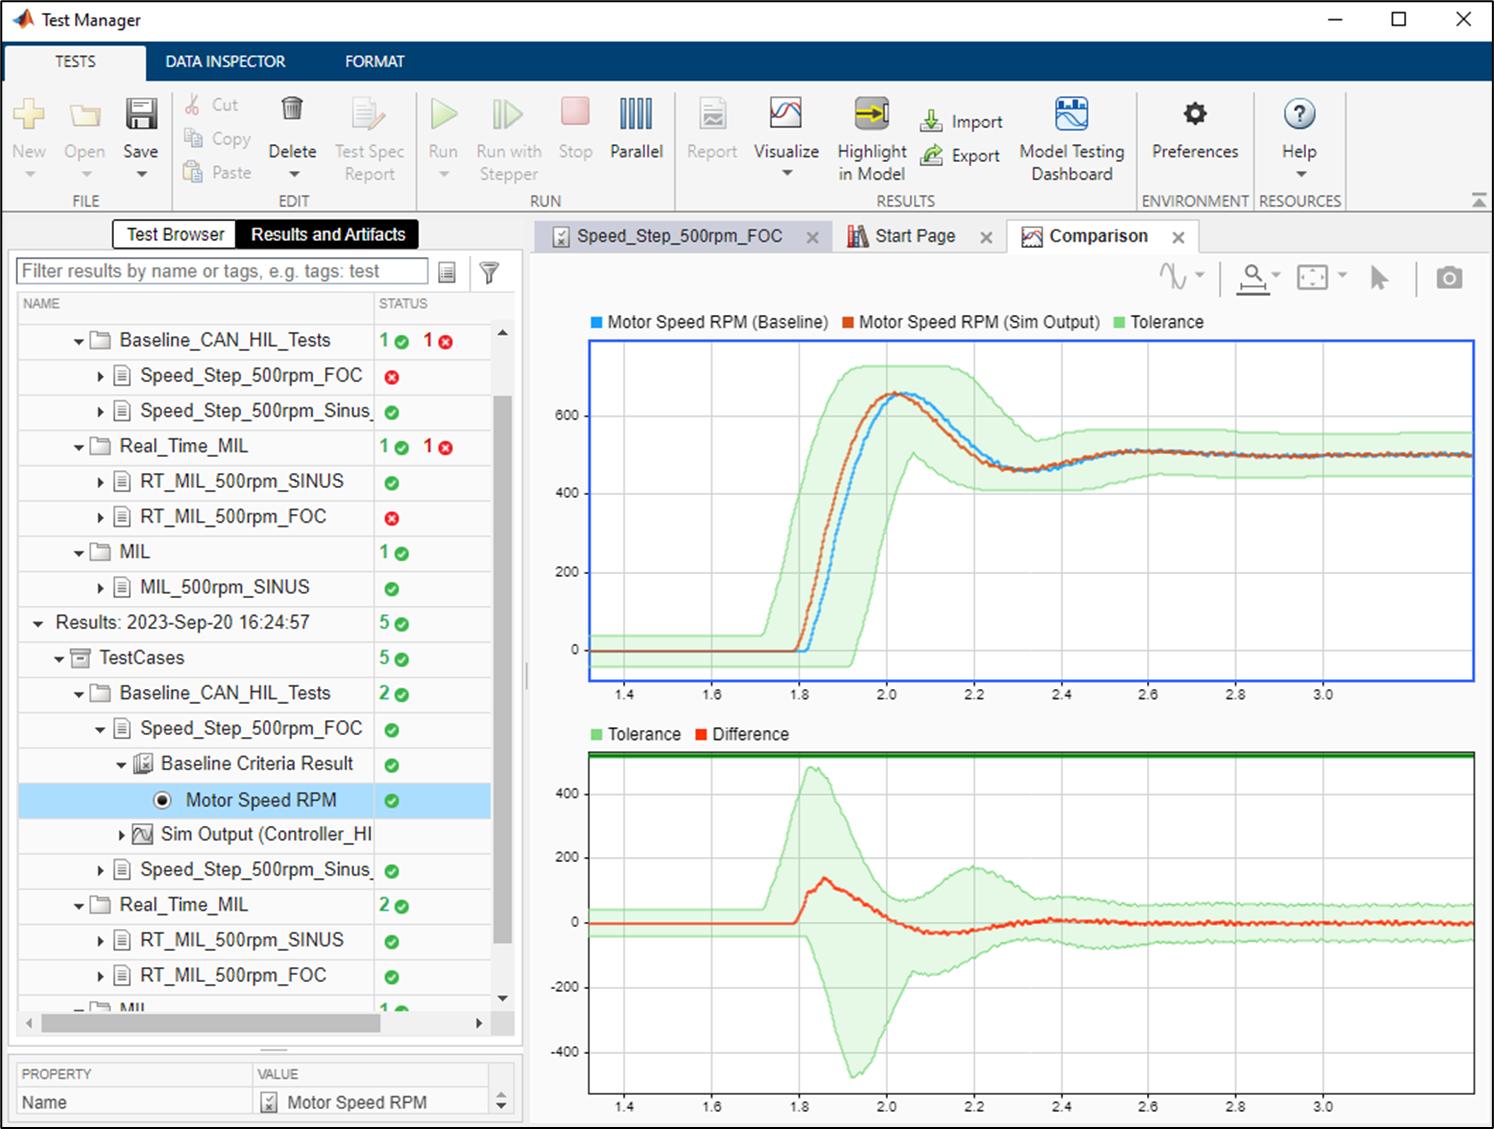

A test harness has also been created to isolate the Controller_HIL_CAN subsystem to be used independently from the user interface and automate the testing of multiple scenarios using the signal editor.

open_system('PMSM3P2LInverterCHILsystem')
sltest.harness.open('PMSM3P2LInverterCHILsystem/Three-Phase PMSM System/Controller/Controller_HIL_CAN','Controller_HIL_CAN_Harness')

#### D3. Continuous Integration

You can use Continuous Integration (CI) workflows to accelerate development and testing of your motor controller. This enables your team to adopt and adhere to [agile development practices](https://ch.mathworks.com/solutions/agile-development.html) throughout your development lifecycle all without losing the benefits of HIL simulation and testing.

You can run MATLAB, Simulink, Simulink Real-Time and Simulink Test on a on-premise HIL CI server and benefit from off-the-shelf integration with mainstay CI platforms like Jenkins, Gitlab or Azure Devops. And all can be orchestrated to work with hardware and complement your HIL testing workflows.

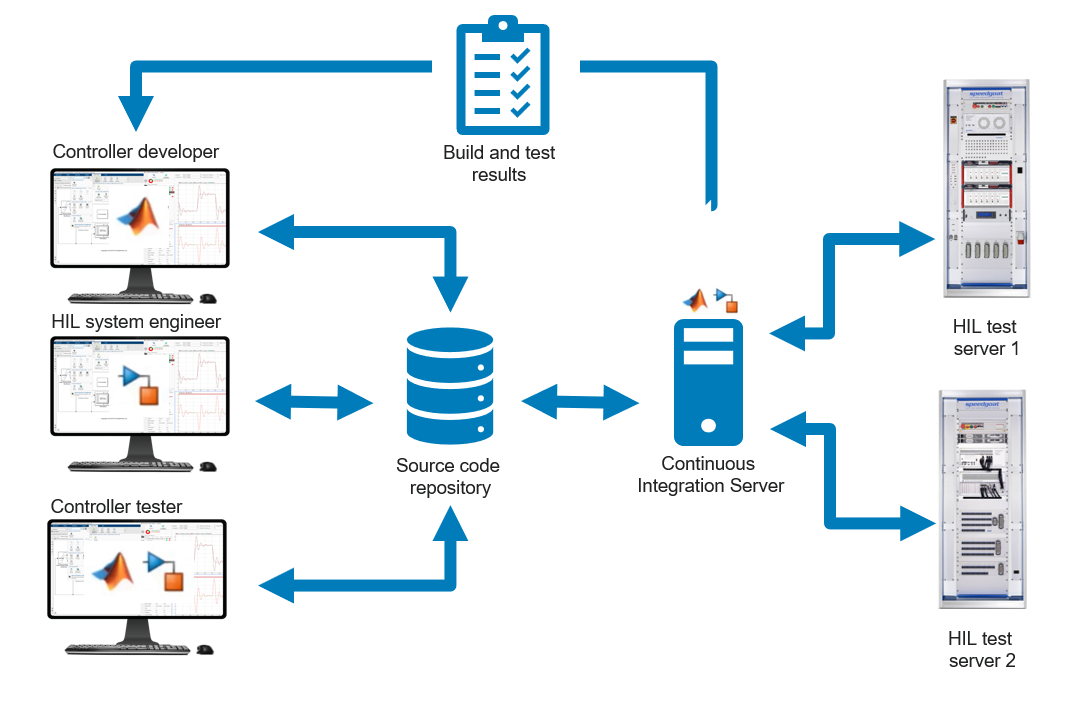

The following command shows an example of a CI pipeline that can be executed in Jenkins, and performs the following actions:

open('RunCItests.m')

- Opens the PMSM3P2LInverterControllerHIL Simulink project

- Assembles a suite of test cases from the Simulink project test artefacts (Simulink Test and MATLAB-based tests)

- Integrates results into Simulink Test Manager

- Creates and executes test runner

- Automatically generates a test report

For a comprehensive demonstration of CI within the context of controller HIL testing, we recommend watching the following webinar: [Automated and Continuous Hardware-in-the-Loop Testing](https://www.speedgoat.com/knowledge-center/webinars/automated-and-continuous-hardware-in-the-loop-testing)

## Related Content

[Three-Phase Two-Level Inverter template](https://www.speedgoat.com/help/hdlcoder/page/sg_help_motioncontrol/refentry_template_pmsm_inverter_c_hil)

## Release Notes

open README.md